**Perceive Medtronic-CU Anschutz Collaboration **

Part 1: Import all nessecary values and create global variables. 

%% loads in json file
%laods in file
cd('C:\Users\sydne\Documents\github\perceive\patientData\Patient2_0604')
jsonFiles = 'Report_Json_Session_Report_20210604T094200.json';
js = jsondecode(fileread(jsonFiles));
%sets it back to the path where all the other functions are
cd('C:\Users\sydne\Documents\github\perceive')

%declares "global" variables AND determines if .json comes from
%single or double battery B)
channels = unique({js.LfpMontageTimeDomain.Channel}, 'stable');
leng = numel({js.LfpMontageTimeDomain.Channel});
startindex = 1; %MUST BE MANUALLY SET IN CLINIC
sides = {'LEFT', 'RIGHT'};
if any((contains(channels, sides{1}))) && any((contains(channels, sides{2})))
    doubleBattery = false;
    %json has both left and right data
    channelsLeft = channels(contains(channels, sides{1}));
    channelsRight = channels(contains(channels, sides{2}));
    channelSides = {channelsLeft, channelsRight}; 
    highestBetas = {' ', ' '};
else
    doubleBattery = true;
end

Part 2: Create freq vs pwr plot for all 6 contacts. Also reports the max betas. 

The highest beta comes from contact pair 02


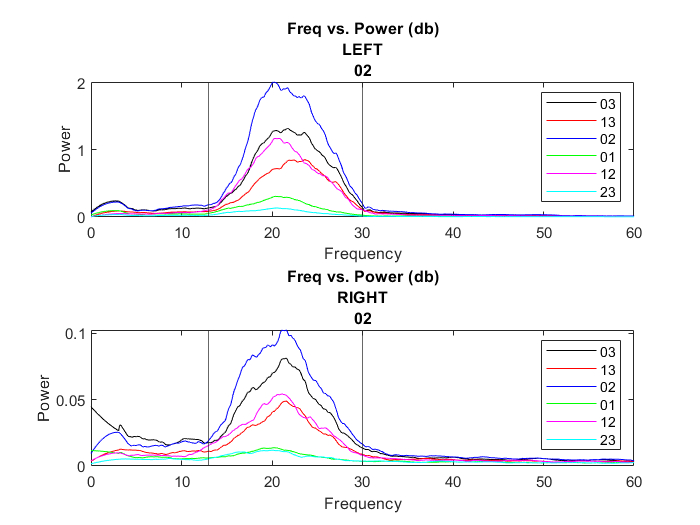

The highest beta comes from contact pair 02


%% run to get full graph
%{} gets the thing from the actual cell array
%() gets cell ARRAY!

close

if doubleBattery == false
    %this should be true if the json returns both left and right data,
    %single battery
    for  i = 1:2
        subplot(2, 1, i)
        channels2 = channels(contains(channels,sides{i}));
        colors = 'krbgmc';
        maxValues = zeros(length(channels2), 1);
        for c=1:length(channels2)
            maxValues(c) = tempAvgPlot(startindex, leng, js, channels2{c}, colors(c));
            hold on;
        end
        
        [M, I] = max(maxValues);
        highestBeta = channels2{I};
        highestBetas{i} = highestBeta;
        
        %add all the plot info
        xline(13);
        xline(30);
        
        %formats the channels to be suitable for the legend
        legendChan = cell(6);
        oldchar = {'LEFT', 'RIGHT', '0', '1', '2', '3', '4', '5', '_', 'AND'};
        newchar = {''};
        oldnum = {'ZERO', 'ONE', 'TWO', 'THREE'};
        newnum = {'0', '1', '2', '3'};
        for b = 1:length(channels2)
            legendChan{b} = replace(channels2{b}, oldchar, newchar);
            legendChan{b} = replace(legendChan{b}, oldnum, newnum);
        end
        
        legend(legendChan{1}, legendChan{2}, legendChan{3}, legendChan{4}, legendChan{5}, legendChan{6})
        title(["Freq vs. Power (db)", sides{i}, legendChan{I}])
        xlim([0 60])
        xlabel("Frequency")
        ylabel("Power")
        
        disp(['The highest beta comes from contact pair ', legendChan{I}])

    end
    
    
else
    %should be true if a double battery
    x = 0;
    %leng = numel({js.LfpMontageTimeDomain.Channel});
    %channels2 = channels(contains(channels,sides{i}));
    
    
    colors = 'krbgmc';
    maxValues = zeros(length(channels), 1);
    for c=1:length(channels)
        maxValues(c) = tempAvgPlot(startindex, leng, js, channels{c}, colors(c));
        hold on;
    end
    
    [M, I] = max(maxValues);
    highestBeta = channels{I};
    
    %add all the plot info
    
    xline(13);
    xline(30);
    
    %these are the order presented in channels
    
    legendChan = cell(6);
    oldchar = {'LEFT', 'RIGHT', '0', '1', '2', '3', '4', '5', '_', 'AND'};
    newchar = {''};
    oldnum = {'ZERO', 'ONE', 'TWO', 'THREE'};
    newnum = {'0', '1', '2', '3'};
    for b = 1:length(channels)
        legendChan{b} = replace(channels{b}, oldchar, newchar);
        legendChan{b} = replace(legendChan{b}, oldnum, newnum);
    end
    
    legend(legendChan{1}, legendChan{2}, legendChan{3}, legendChan{4}, legendChan{5}, legendChan{6})
    title(["Freq vs. Power (db)", legendChan{I}])
    xlim([0 60])
    xlabel("Frequency")
    ylabel("Power")
    
    disp(['The highest beta comes from contact pair ', legendChan{I}])
end

Part 3: Compare beta values with stds across contacts 

Max Betas LEFT


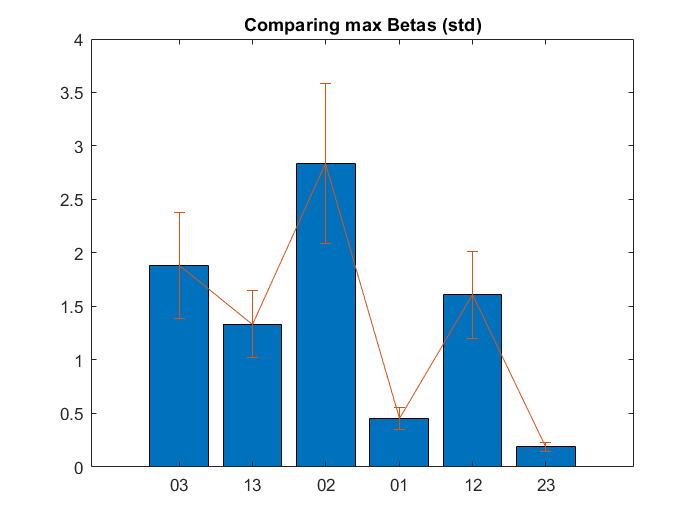

Max Betas RIGHT


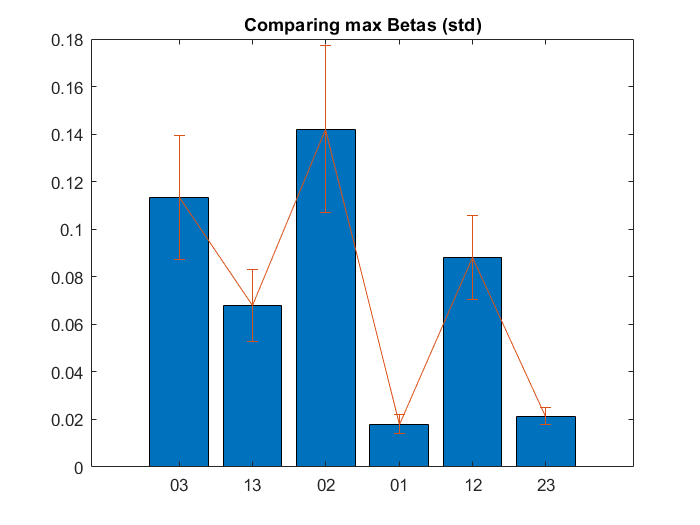


if doubleBattery == false
    for i = 1:2 
        disp(['Max Betas ', sides{i}])
        compareBetaBarChart(startindex, leng, js, channelSides{i});
        figure; 
    end
else 
    compareBetaBarChart(startindex, leng, js, channels);
end

Part 4: Show table of data across each run 

if doubleBattery == false
    for i = 1:2 
        disp(['Table of means and stds per channel ', sides{i}])
        maxMeanBetaAllRuns(startindex, js, leng, channelSides{i});
        figure; 
    end
else 
    maxMeanBetaAllRuns(startindex, leng, js, channels);
    figure; 
end

Table of means and stds per channel LEFT


ans = 6×7 table
              Var1              Mean R1     Mean R2     Mean R3     STD R1      STD R2      STD R3 
    ________________________    ________    ________    _______    ________    ________    ________

    {'ZERO_TWO_LEFT_2'     }      1.1235      1.3256     1.0068     0.87504     0.93069     0.74441
    {'ZERO_THREE_LEFT_0'   }     0.68224      0.9442    0.70638     0.53611     0.65692     0.50726
    {'ONE_AND_TWO_LEFT_1'  }     0.65589     0.69293     0.5461     0.49253     0.43155     0.45486
    {'ONE_THREE_LEFT_1'    }     0.42279     0.58601    0.46806     0.33974     0.40995     0.35274
    {'ZERO_AND_ONE_LEFT_0' }      0.1503     0.18418    0.15133     0.11469     0.11598      0.1287
    {'TWO_AND_THREE_LEFT_2'}    0.074978    0

Table of means and stds per channel RIGHT


ans = 6×7 table
              Var1                Mean R1      Mean R2      Mean R3      STD R1       STD R2       STD R3  
    _________________________    _________    _________    _________    _________    _________    _________

    {'ZERO_TWO_RIGHT_5'     }     0.050325     0.077603     0.057598     0.037565     0.057483     0.032637
    {'ZERO_THREE_RIGHT_3'   }     0.040915     0.057103     0.042317     0.028979       0.0414     0.025036
    {'ONE_AND_TWO_RIGHT_4'  }     0.035766     0.032432     0.026359     0.030524     0.019073     0.012064
    {'ONE_THREE_RIGHT_4'    }     0.024048     0.031501     0.025468     0.016749     0.021688     0.014984
    {'ZERO_AND_ONE_RIGHT_3' }    0.0087138    0.0086466    0.0079615     0.005922      0.00486   

Part 5: Show all frequency data for contact pair that provides highest beta 

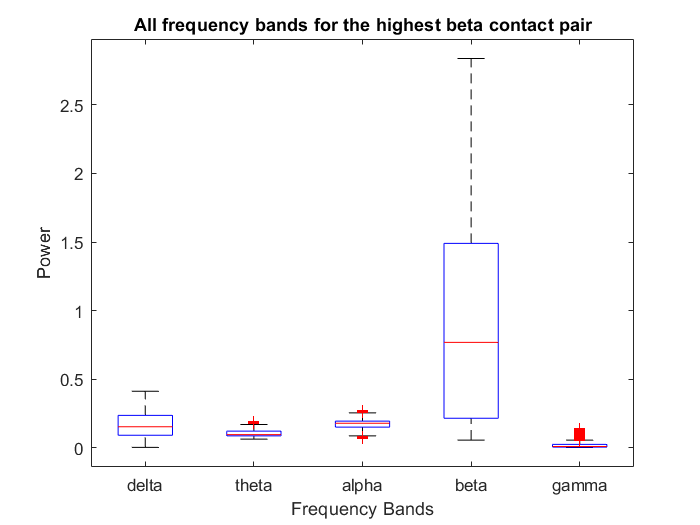

All frequency data for 02LEFT


All frequency data for 02RIGHT


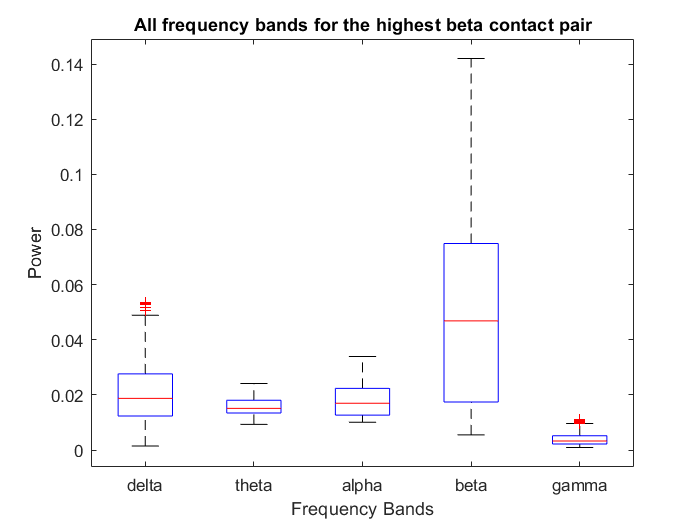

figure;
if doubleBattery == false
    for i = 1:2 
        disp(['All frequency data for ', legendChan{I}, sides{i}])
        allFreqBarChart(startindex, leng, js, highestBetas{i});
        figure; 
    end
else 
    allFreqBarChart(startindex, leng, js, highestBeta);
    figure; 
end

Part 6: Show variability between trials for each pair 

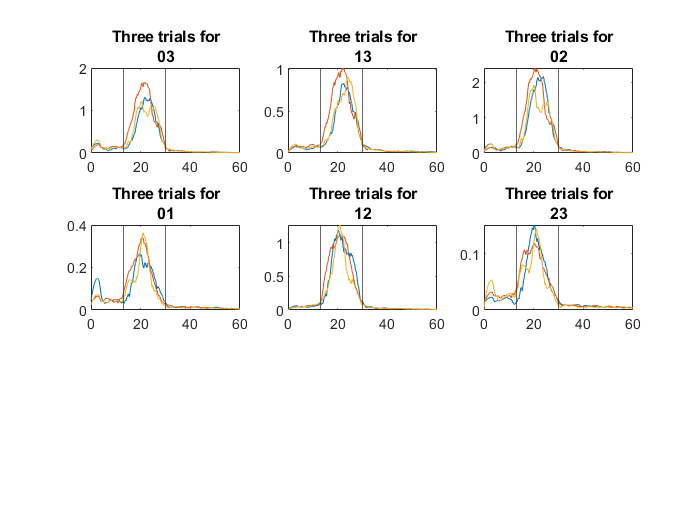

Trial variability for the LEFT


Trial variability for the RIGHT


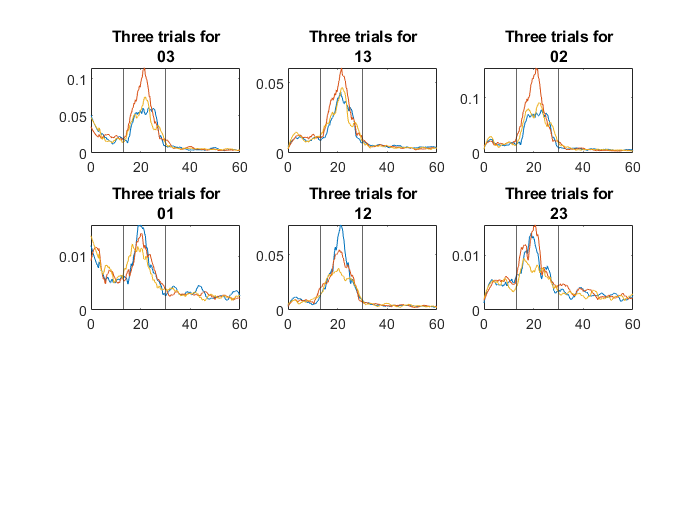

%graphEachTrials(startindex, js, leng, channels);
figure;
if doubleBattery == false
    for i = 1:2 
        disp(['Trial variability for the ', sides{i}])
        graphEachTrials(startindex, js, leng, channelSides{i});
        figure; 
    end
else 
   graphEachTrials(startindex, js, leng, channels);
   figure; 
end